# Building the vicsek model

## Initial setup

Creating a lattice of random unit vectors

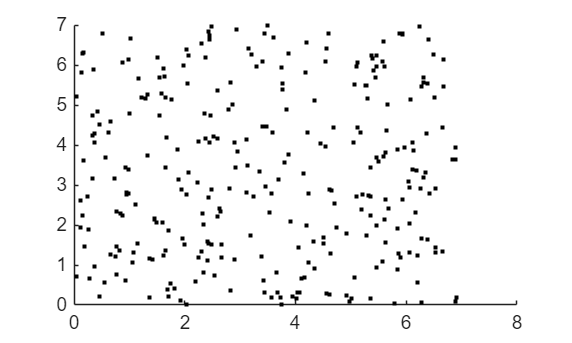

N = 300;
L = 7;
x = L.*rand(1,N);
y = L.*rand(1,N);
eta = 0.02;
velocity = 0.03;
scaling_factor = (L^2)*8/N;
scatter(x, y, "black.");
hold on

Adding vectors to them-assigning random directions

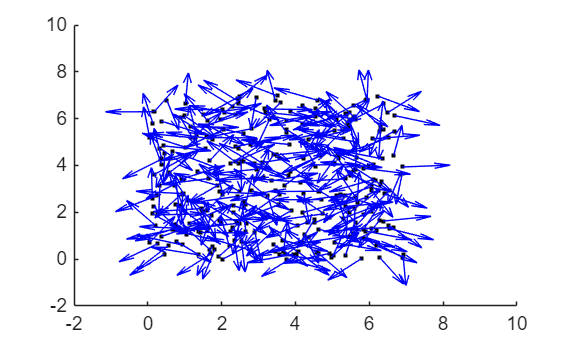

theta =  2*pi.*rand(1,N);
u = scaling_factor*cos(theta);
b = scaling_factor*sin(theta);
quiver(x, y, u, b, 0, 'blue'); % Plot unit vectors in red
% for i = 1:N
%     text(x(i)+0.01, y(i)+0.01, string(i), 'Color','white');
% end

% neighbours_of_i = find_neighbours(1, x, y, 0.3, N) %neighbours are being found properly
% [theta_average, updated_x, updated_y] = diksuchi(1, x, y, u, b, theta, neighbours_of_i, eta, velocity, epsilon, L)
% scatter(updated_x, updated_y, 'green.');
hold off;

 % Release the plot

## Get the wheel of time turning

A function to update direction based on average direction of neighbours within a radius

## trial runs

## Simulation over time

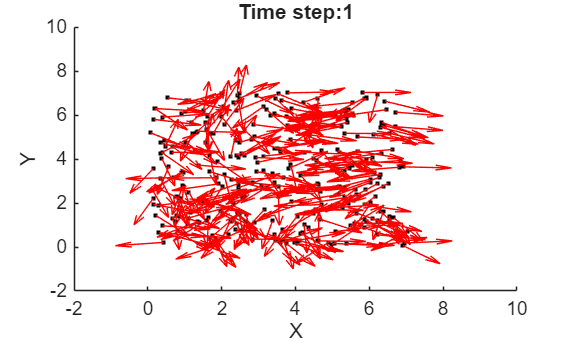

T = 500; % number of time steps
r = 1;
epsilon = 0.05;

x_t_i = x;
y_t_i = y;
theta_t_i = theta;

figure;
xlim([0 L]);
ylim([0 L]);

video_filename = 'vicsek.avi';
writer = VideoWriter(video_filename); 
open(writer);
metrics = zeros(1,T);
track_x_i = zeros(1,T);
track_y_i = zeros(1,T);

for j = 1:T
    for i = 1:N
        ngh = find_neighbours(i, x_t_i, y_t_i, r, N);
        [theta_average, updated_x, updated_y] = diksuchi(i, x_t_i, y_t_i, u, b, ngh, eta, velocity, epsilon, L);
        x_t_i(i) = updated_x;
        y_t_i(i) = updated_y;
        theta_t_i(i) = theta_average; % Update the direction for the next time step
        % theta_t_i
    end
    u_t_i = scaling_factor*cos(theta_t_i);
    v_t_i = scaling_factor*sin(theta_t_i);

    metrics(j) = metric(N, velocity, u_t_i, v_t_i);
    track_x_i(j) = x_t_i(7);
    track_y_i(j) = y_t_i(7);

    cla;
    xlim([0 L]);
    ylim([0 L]);
    scatter(x_t_i, y_t_i, "black.");
    hold on;
    quiver(x_t_i, y_t_i, u_t_i, v_t_i, 0, 'r');
    % for i = 1:N 
    %     text(x_t_i(i)+0.01, y_t_i(i)+0.01, string(i), 'Color','white');
    % end
    % scatter(track_x_i, track_y_i, 'black.');
    hold on;
    
    title(['Time step:' num2str(j)]);
    xlabel('X');
    ylabel('Y');
    drawnow;
    frame = getframe(gcf);
    writeVideo(writer, frame); % Use the new variable name 'writer'
    % hold off;
end

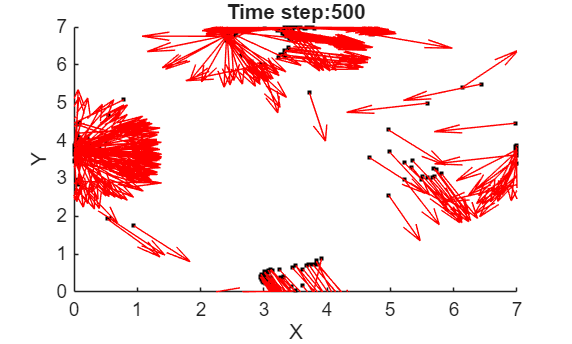


close(writer); 
hold off

t = 1:T ;
scatter(t, metrics)
hold off

## Funtions

function neighbours = find_neighbours(poi_n, x, y, r, N)
    %poi = particle of interest
    x_n = zeros(1, N);
    y_n = zeros(1, N);
    poi_x = x(poi_n);
    poi_y = y(poi_n);
    n_coords = zeros(1, N);
    for i = 1:N
        if (poi_y-r)< y(i) && y(i) < (poi_y+r)
            if (poi_x-r)< x(i) && x(i) < (poi_x+r)
                dist = sqrt((y(i)-poi_y)^2 + (x(i)-poi_x)^2);
                if dist < r && dist > 0
                    y_n(i) = y(i);
                    x_n(i) = x(i);
                    n_coords(i) = i;
                end
            end
        end
    end
    neighbours = n_coords(n_coords ~= 0);
end

function [theta_avg, x_t1, y_t1] = diksuchi(poi_n, x, y, u, v, neighbours, eta, velocity, epsilon, L)
    n = neighbours;
    no_n = numel(n);
    
    if no_n > 0 
        u_n = zeros(1,no_n);
        v_n = zeros(1,no_n);
        for i = 1:no_n
            u_n(i) = u(n(i));
            v_n(i) = v(n(i));
        end
    else 
        u_n = u;
        v_n = v;
    end

    noise = -eta/2 + eta*rand(1);
    a = mean(v_n);
    c = mean(u_n);
    theta_avg = atan(a/c) + noise;
    if a < 0 && c < 0
        theta_avg = theta_avg + pi;
    end

    x_t1 = x(poi_n) + velocity*cos(theta_avg)*1;
    y_t1 = y(poi_n) + velocity*sin(theta_avg)*1;

    if x_t1 > L
        x_t1 = x_t1 - L;
    elseif x_t1 < epsilon
        x_t1 = x_t1 + L;
    end

    if y_t1 > L
        y_t1 = y_t1 - L;
    elseif y_t1 < epsilon
       y_t1 = y_t1 + L;
    end
    
end

function va = metric(N, velocity, u, v)
    va = (1/(N*velocity))*(abs(sum(u)+ sum(v)));
end

% function [x, y] = track_one_spp(x_t_1, y_t_1, u_t_1, v_t_1)
% 
% end